# **IO3xx Serial Loopback**

This example shows how to perform a loopback test using IO3xx Serial. You can test the basic IO3xx serial functionality by running this example.

## Setup

### Prerequisites

You will require the following to run this example:

- A Speedgoat real-time target machine with one I/O module from the IO3xx family installed

- A Speedgoat configuration file that supports **1x serial channels**

- A connector cable from the I/O module to the terminal board

- A terminal board with jumper wires

### Test Setup

In this example, the Tx  and the Rx line of serial channel 1 is looped back. You must therefore connect the pins on the terminal board where these channels are located. The exact pins depend on the configuration file used.

In the pin mapping of your configuration file, locate the functionalities specified in the table below and then locate the corresponding pins on the terminal board. Connect these pins with jumper wires. 

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_Serial_Loopback';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

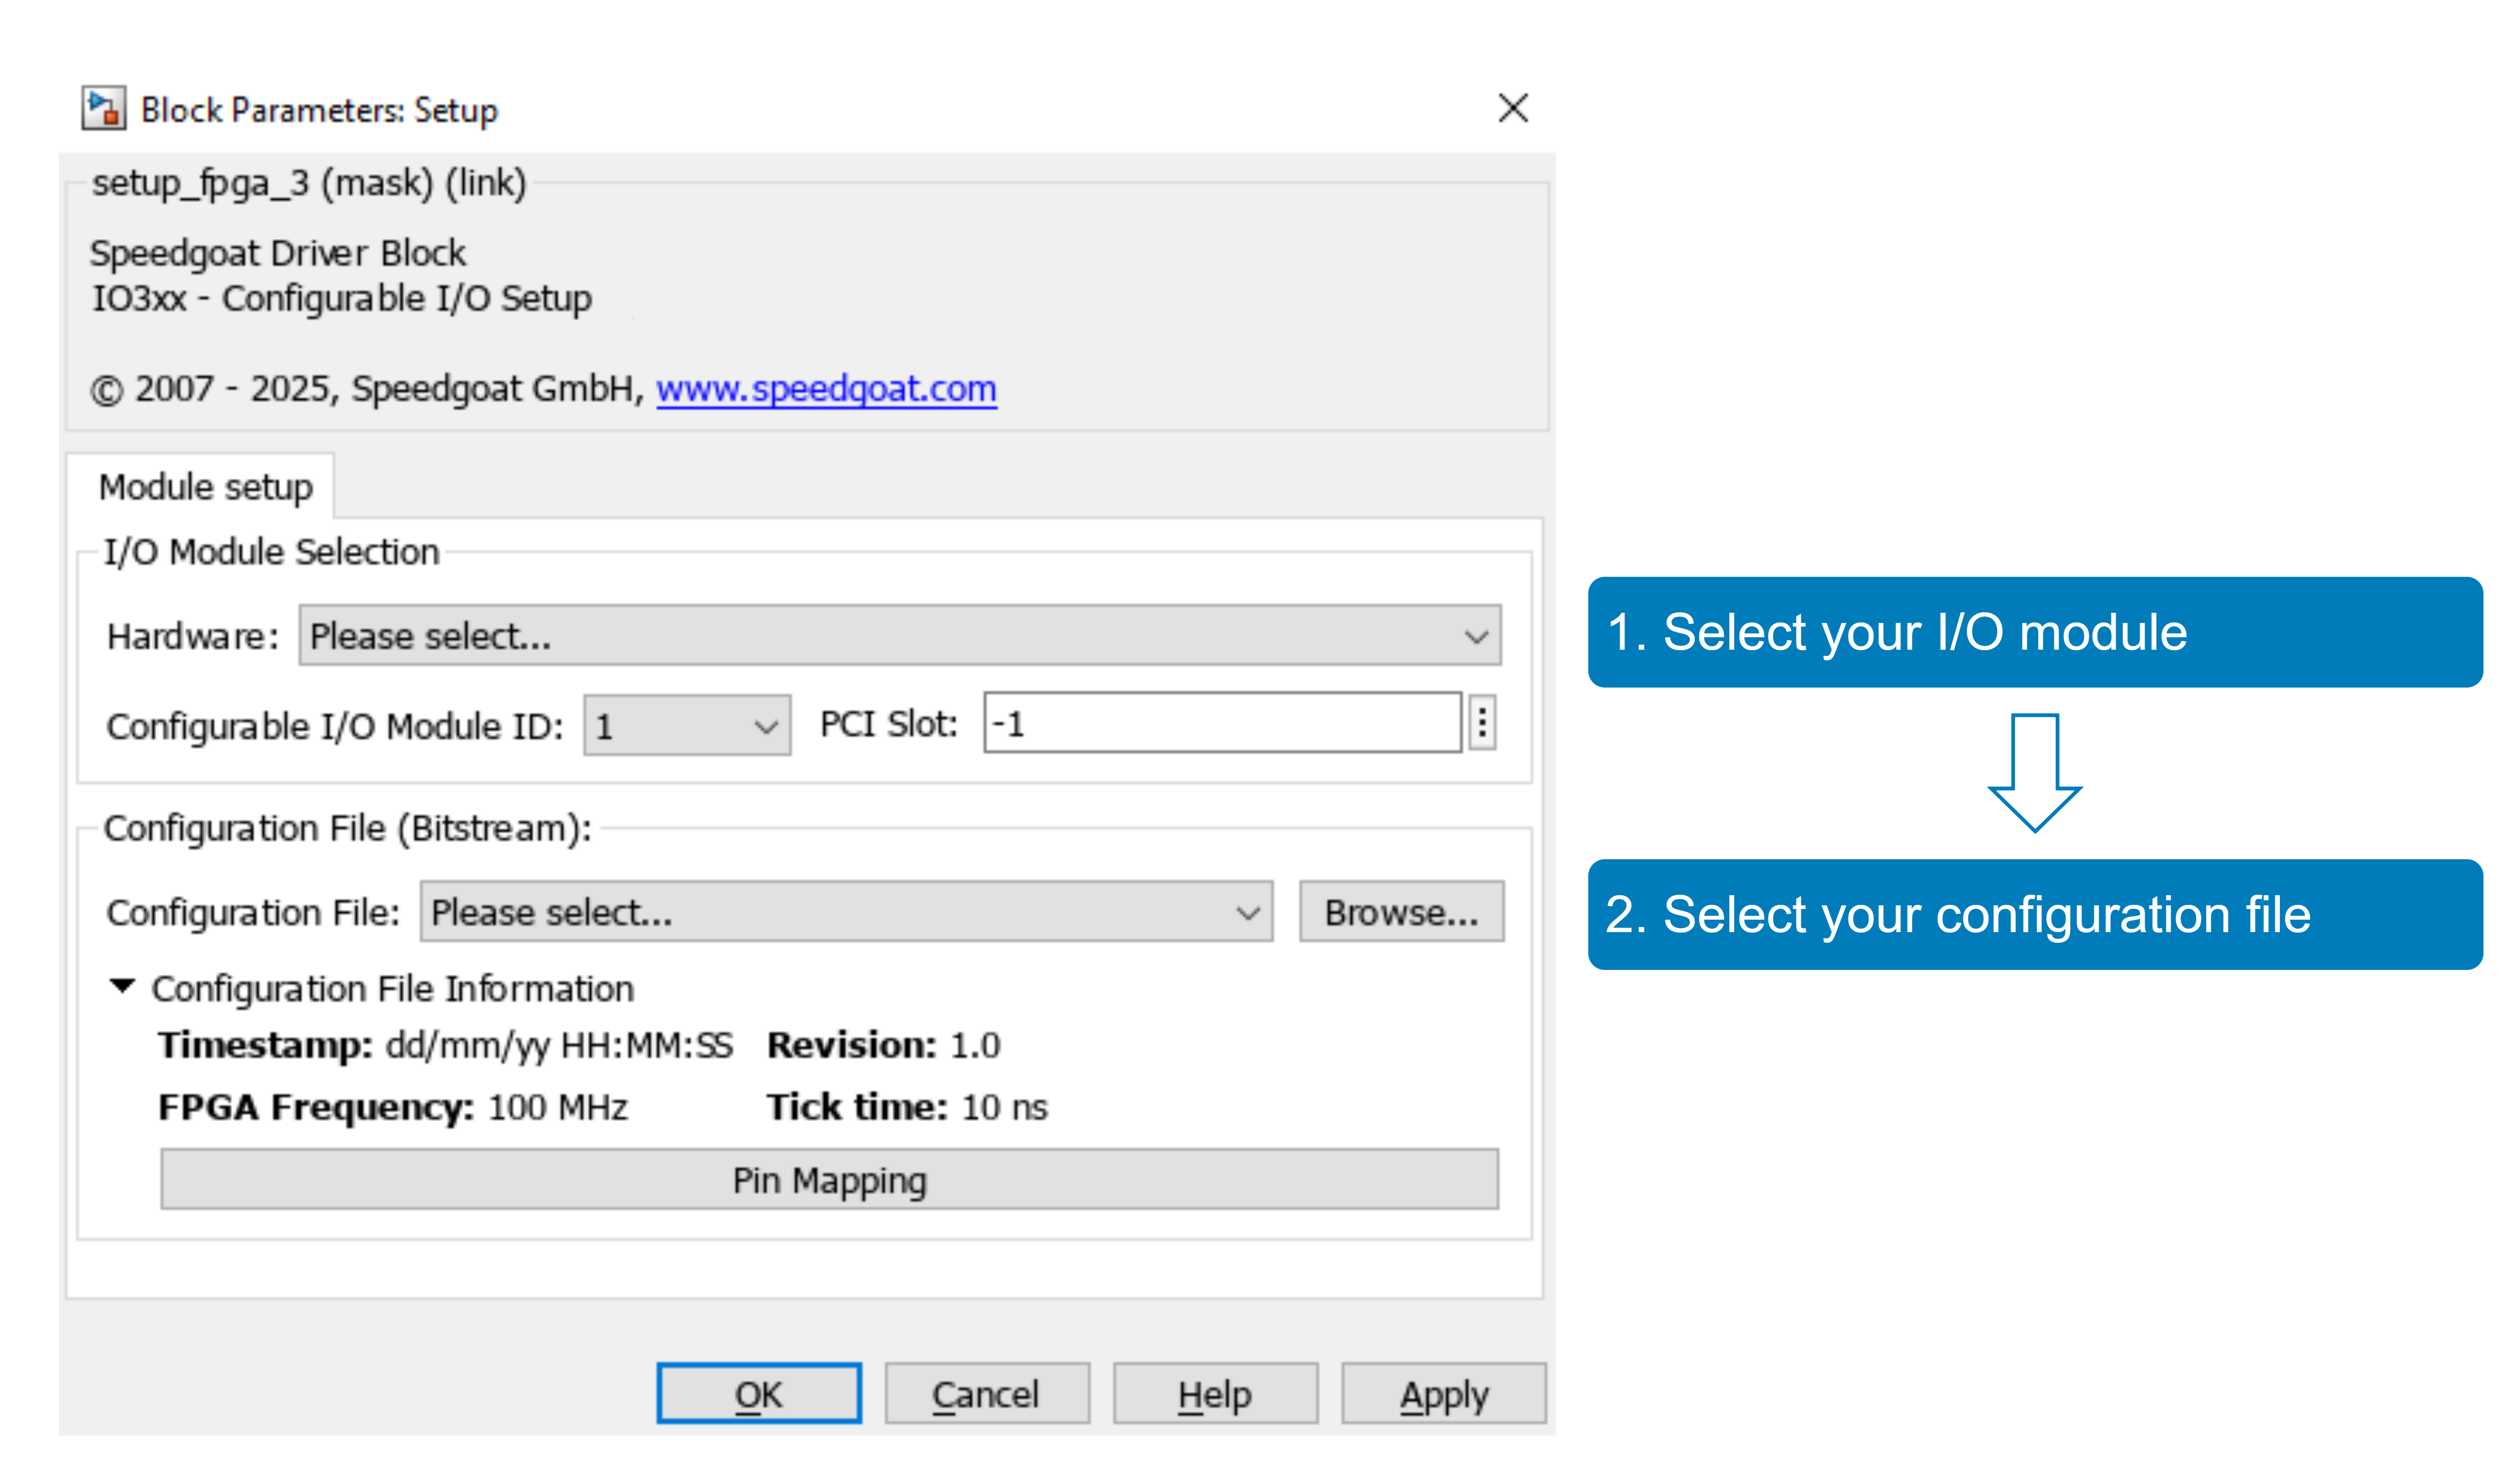

With the **Pin Mapping** button you can now check where the functionalities are located.

### Model Description

In this model, serial channel 1 transmits a vector of data and receives it. The scope displays the received data and the number of bytes received. 

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model:

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);
tg.setStopTime(10);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode','external')    % put model into External Mode
set_param(modelName,'SimulationCommand','connect')  % connect with External Mode  

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check the loopback is working as expected, open the Simulink scope that is connected to the Serial Read block. The scope must display the number of received bytes and the serial data:

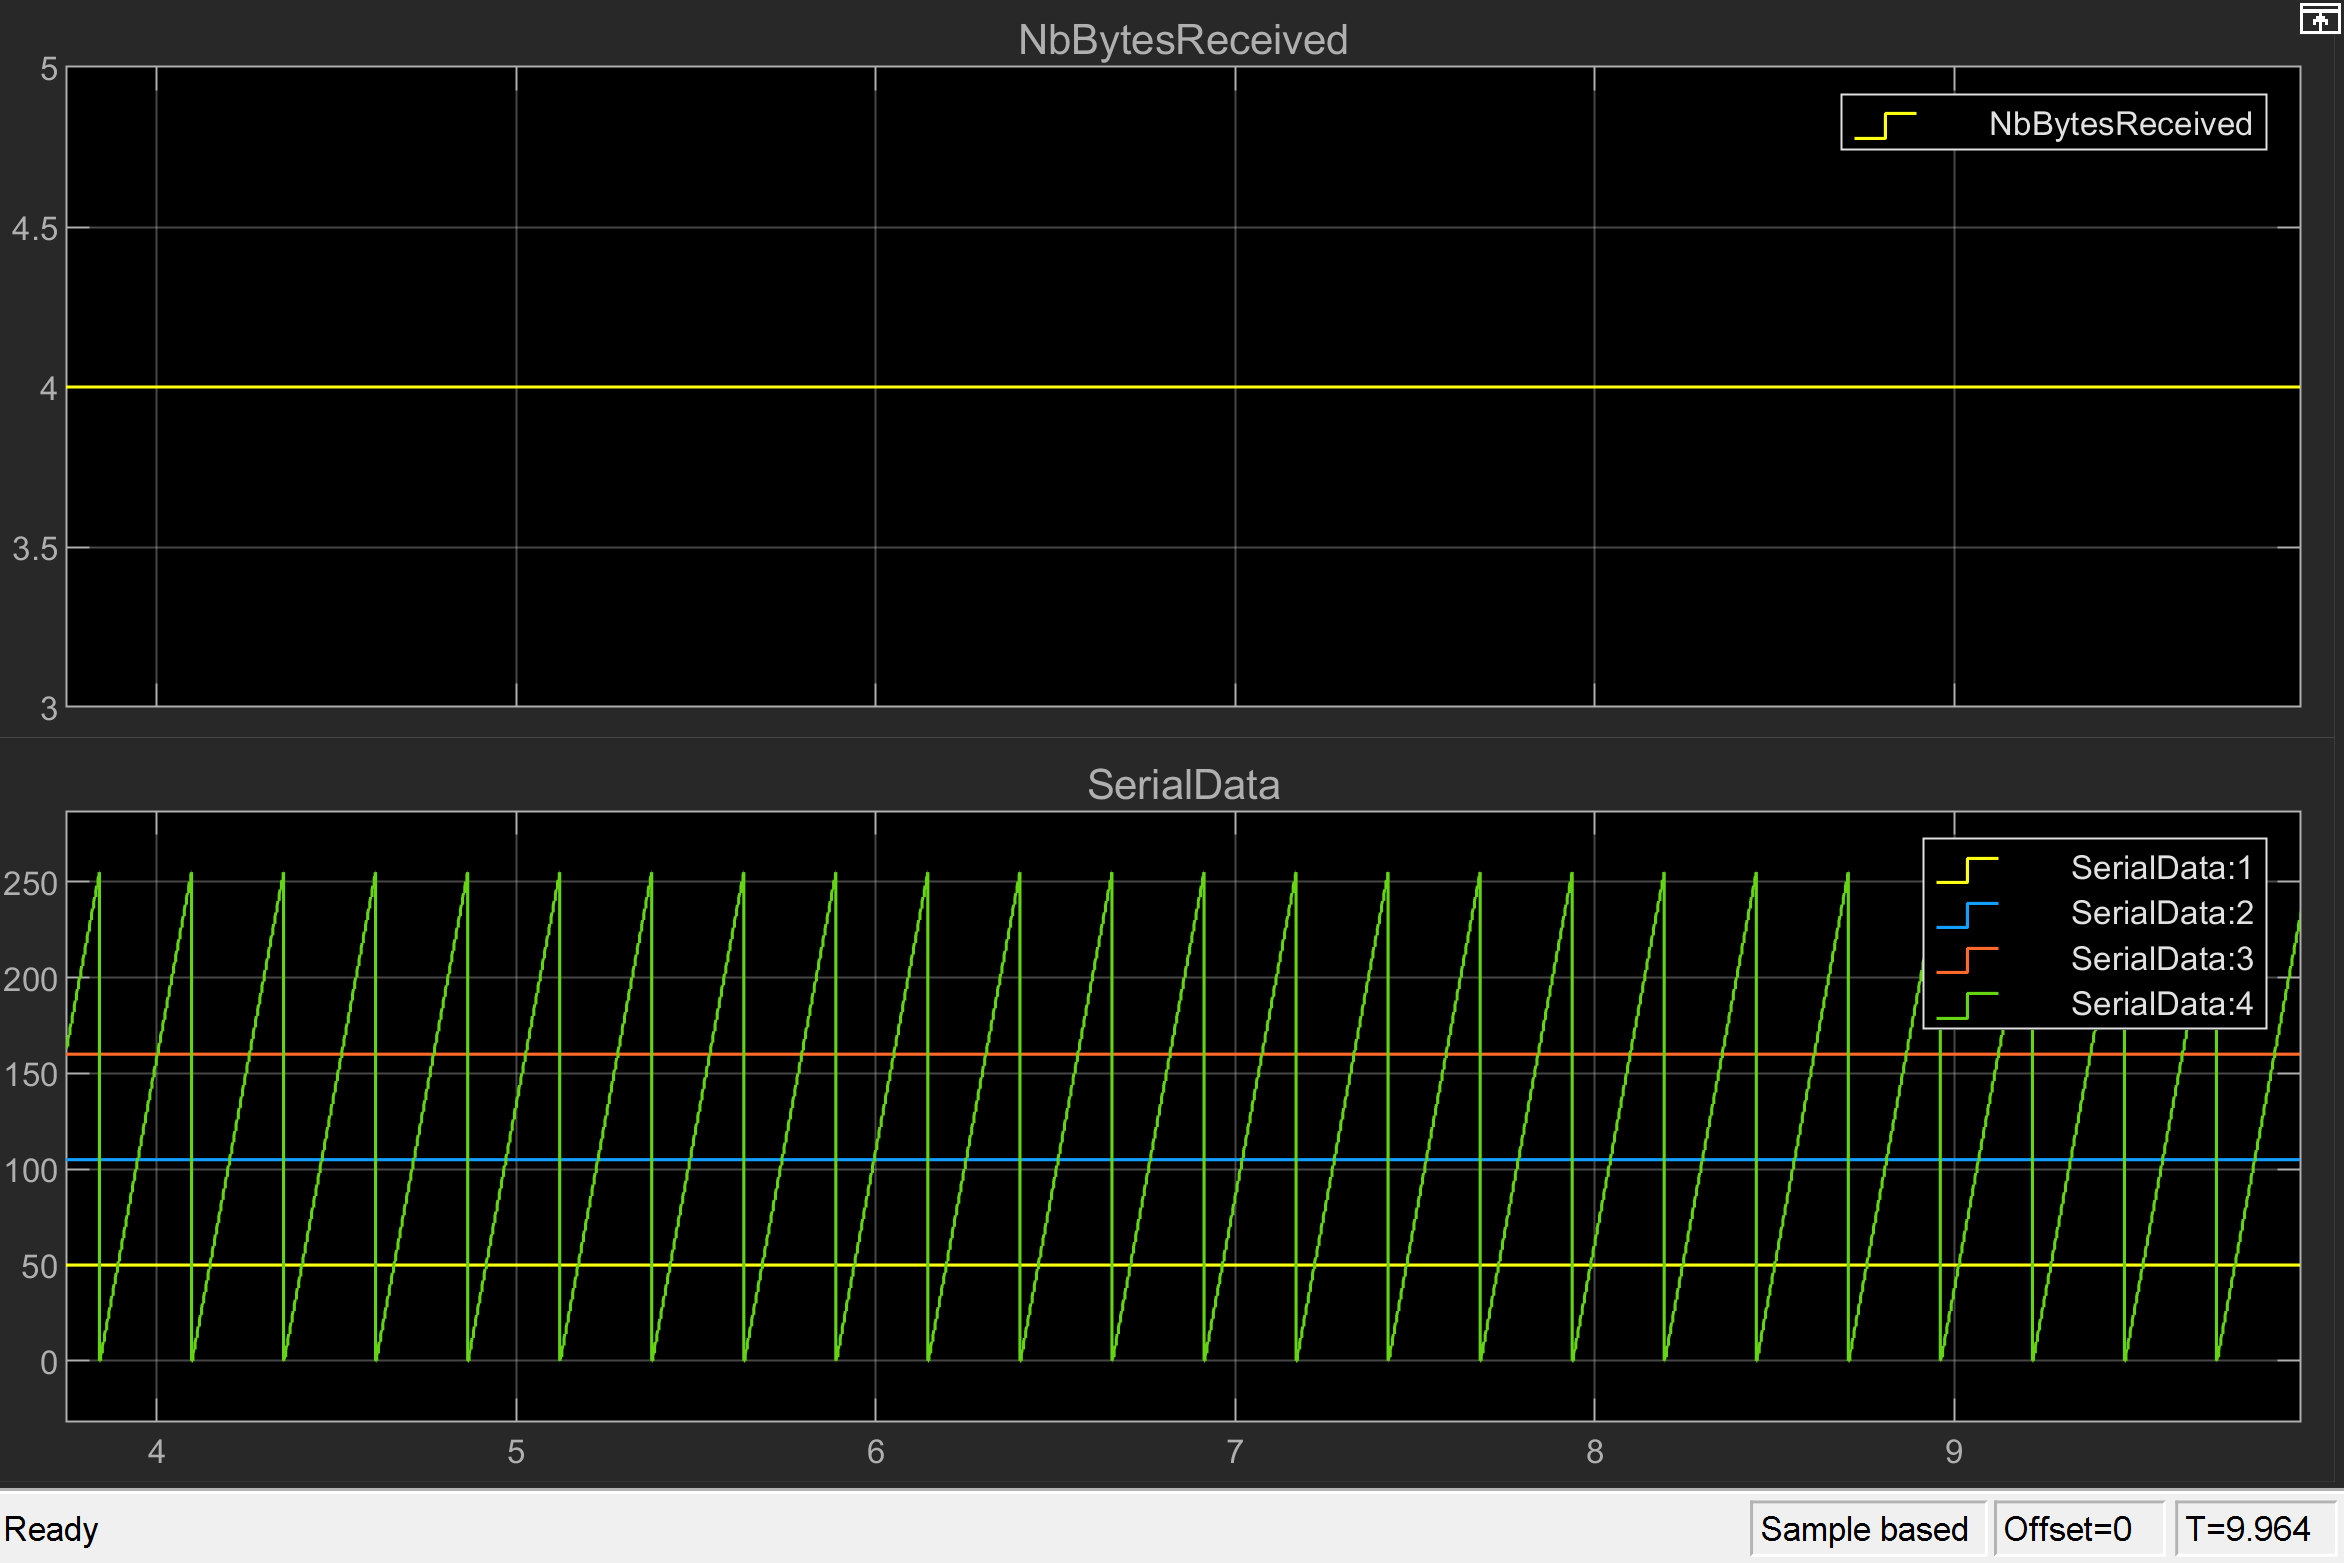

## Additional References

- [IO3xx Serial Documentation and Examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_serial)